clear 
close all

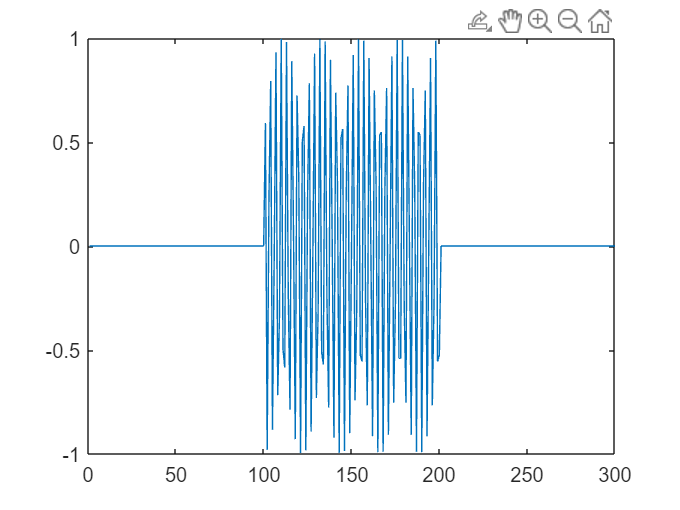

x_n = [zeros(1,100) ones(1,100) zeros(1,100)];
n = 1:300;
plot(n, exp(1j*2*n).*x_n)

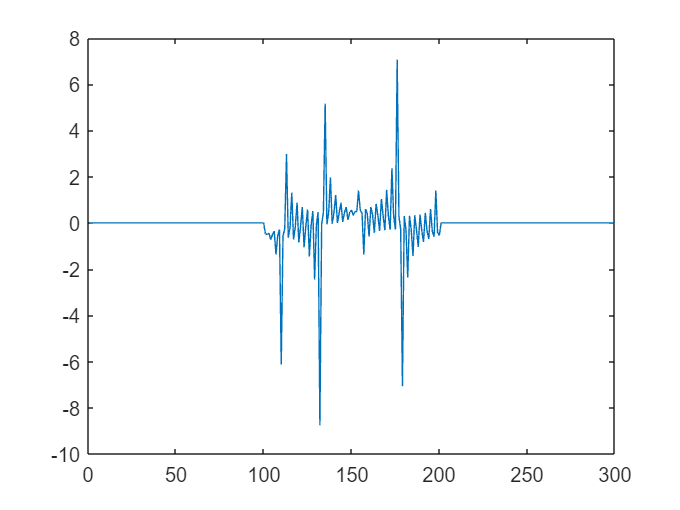

X_n = zeros(1,300);
for i = 1 :2: 200
    X_n = X_n + exp(1j*i*n).*x_n;
end
plot(n, X_n)

%(a) In low noise rxsig, QAM OFDM signal shows clearly 4 dots.
%(b)

run("pss0.m")
run("pss1.m")
run("pss2.m")
run("pss.m")
run("dseq.m")
%run("sss.m")
load("rx151024mat.mat")
load("rxsignal_justnoise.mat")
load("rxsignal_withchannel.mat")
load("rxsignal_withchannelandfreqoff.mat")
fs = 61.44e6;
pssi_t_all = [pss0_t;pss1_t;pss2_t];
pssi_f_all = [pss_0,pss_1,pss_2];

% detect the position for SSB extraction
rx_sig = rx151024; %choose signal
rx_sig = rx_sig - mean(rx_sig);
[Y1, pos1,num] = PSS_MFdetc(rx_sig, pss0_t,pss1_t,pss2_t);%detect signal

pss0 detected
With value:


MAX_value = 4.4387e+06

In position:


ans = 384273

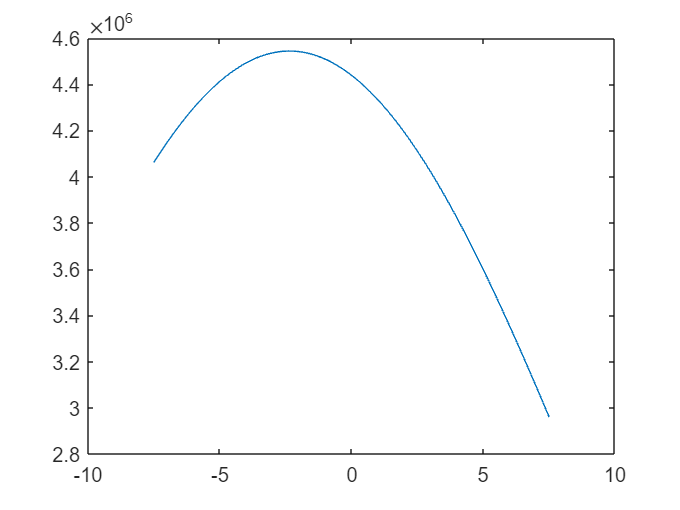

best_offset_freq = -2.4000

max_outcome = 4.5434e+06

freq_scan = 1.0e+06 *

    4.0621    4.0798    4.0972    4.1144    4.1312    4.1478    4.1640    4.1800    4.1956    4.2110    4.2260    4.2407    4.2551    4.2692    4.2829    4.2963    4.3094    4.3222    4.3346    4.3466    4.3584    4.3698    4.3808    4.3915    4.4019    4.4119    4.4215    4.4308    4.4398    4.4483    4.4566    4.4644    4.4719    4.4790    4.4858    4.4922    4.4982    4.5038    4.5091    4.5140    4.5186    4.5227    4.5265    4.5299    4.5329    4.5355    4.5378    4.5397    4.5412    4.5423


pssi_t = pssi_t_all(num,:);
pssi_f = pssi_f_all(:,num);
[best_offset_freq, max_outcome, freq_scan] = freq_offset_detect(pssi_t,rx_sig,7.5,2,fs)

%doing the frequency offset compansation
n = 1: length(pssi_t);
offset_seq = exp(-2*pi.*n*1j*best_offset_freq*1e3/fs);
pssi_reset = pssi_t.*offset_seq;
m = 1: length(rx_sig);
offset_seq = exp(-2*pi.*m*1j*best_offset_freq*1e3/fs);
rx_sig_reset = rx_sig.*offset_seq';
[Y2, pos2] = PSS_MFdetc(rx_sig, pss0_t, pss1_t, pssi_reset);

pss2 detected
With value:


MAX_value = 4.5434e+06

In position:


ans = 384273

% pos2 = pos1;
% rx_sig_reset = rx_sig;

Block_number = 0

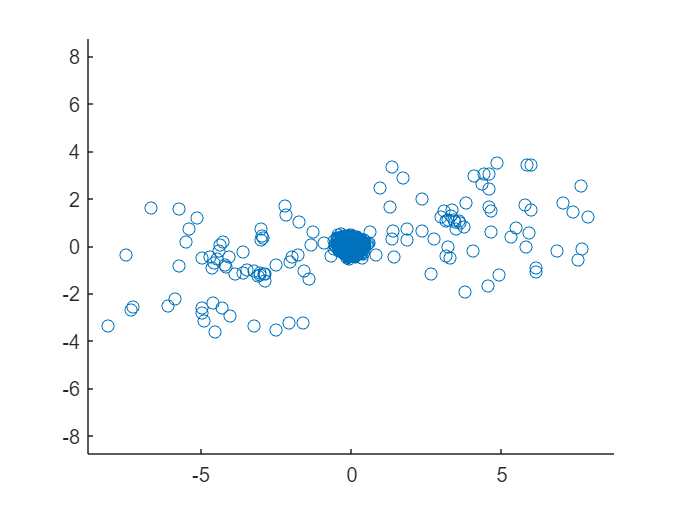

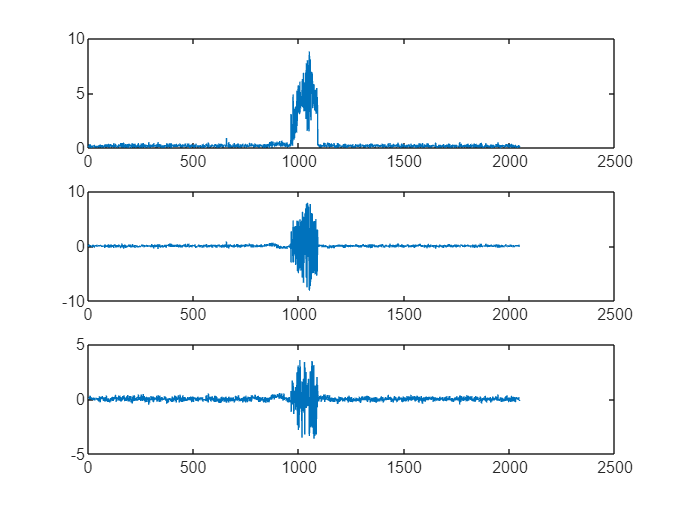

Block_number = 1

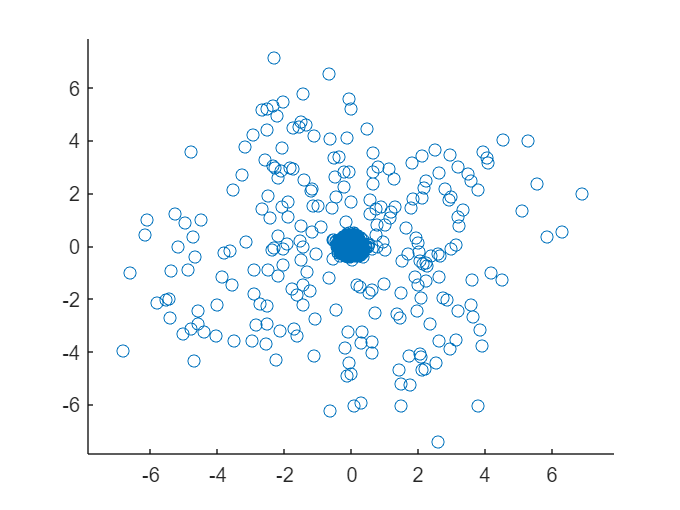

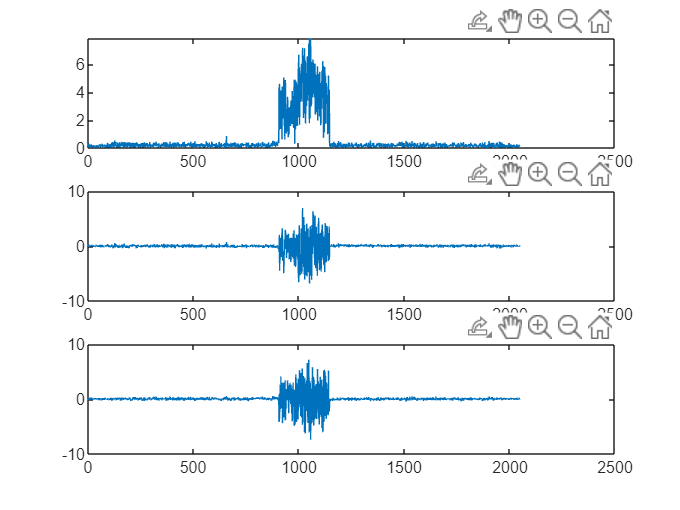

Block_number = 2

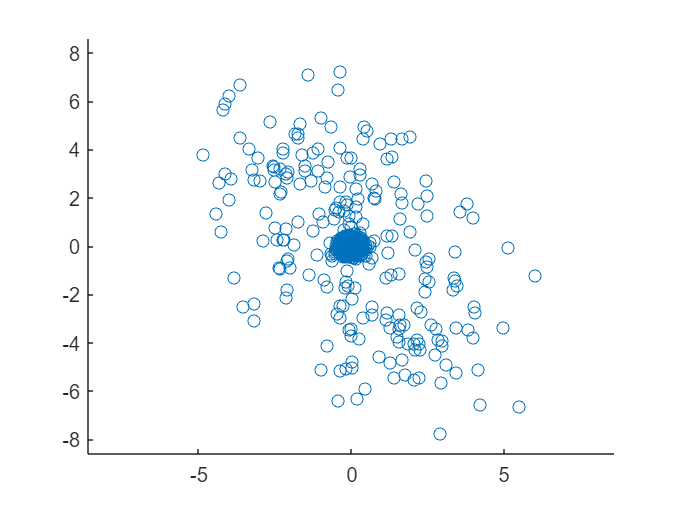

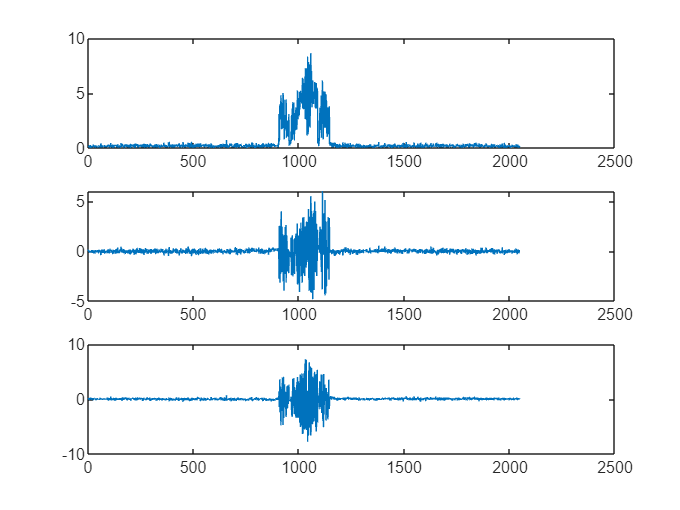

Block_number = 3

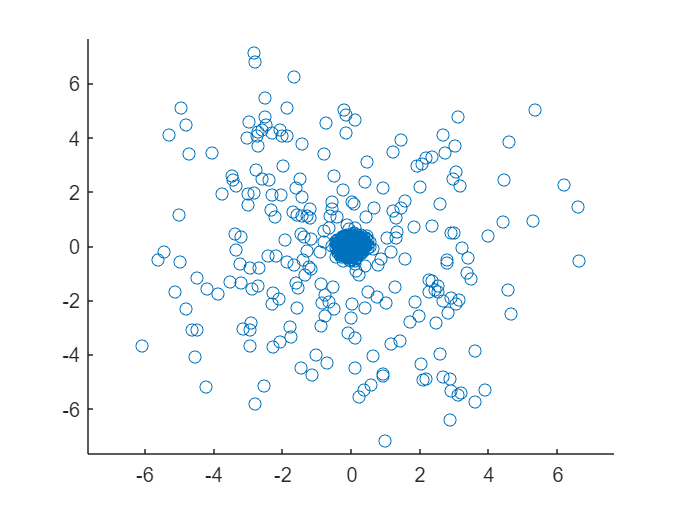

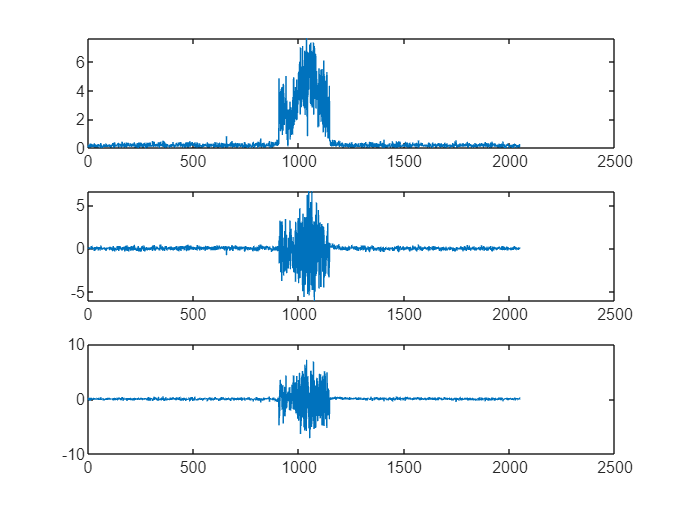

%prefix remove
N = 1;
M = 4;
SSB = zeros(M,2048);
fft_SSB = zeros(M,2048);
Start = pos2(num)-2192+1+144;%循环前缀去掉
End = Start+2048-1;%OFDM符号长度
for i = N:N+M-1
    SSB(i,:) = rx_sig_reset(Start:End)';
    Start = End+1+144;
    End = Start+2048-1;
    [fft_SSB(i,:),f] = FFT(SSB(i,:),fs);
    Block_number = i-1
    figure
    scatter(real(fft_SSB(i,:)),imag(fft_SSB(i,:)))
    L = max(abs(fft_SSB(i,:)));
    axis([-L L -L L])
    figure
    subplot(3,1,1)
    plot(1:2048,abs(fft_SSB(i,:)))
    subplot(3,1,2)
    plot(1:2048,real(fft_SSB(i,:)))
    subplot(3,1,3)
    plot(1:2048,imag(fft_SSB(i,:)))
end

Block_number = 0

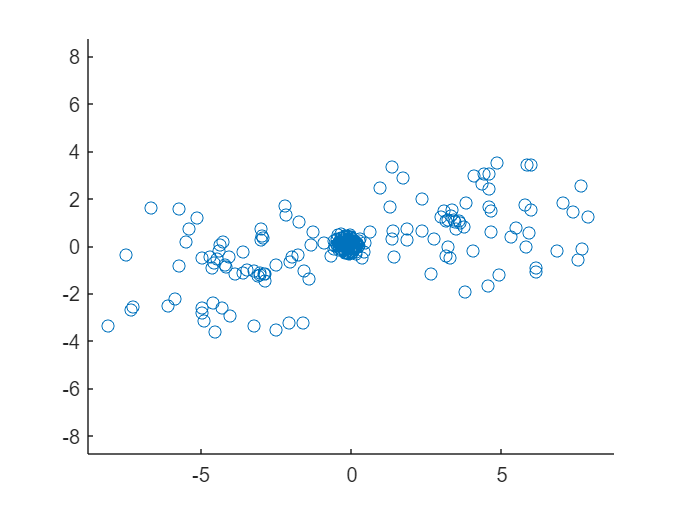

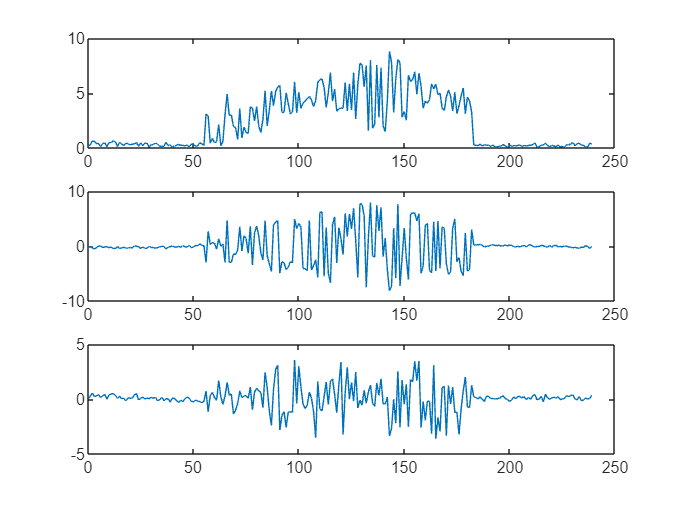

Block_number = 1

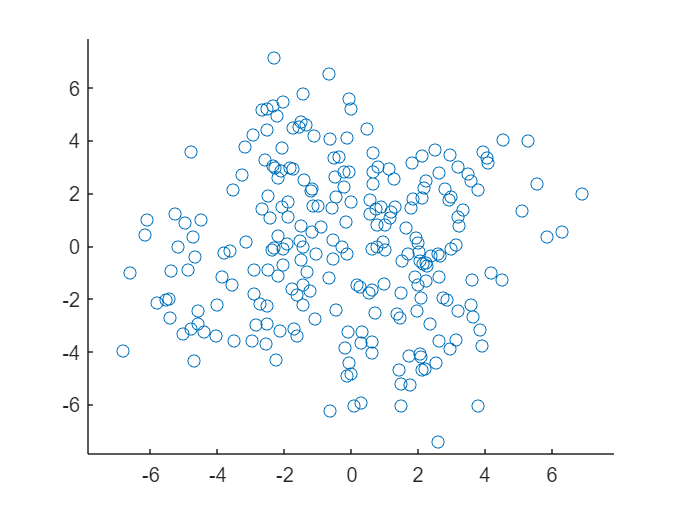

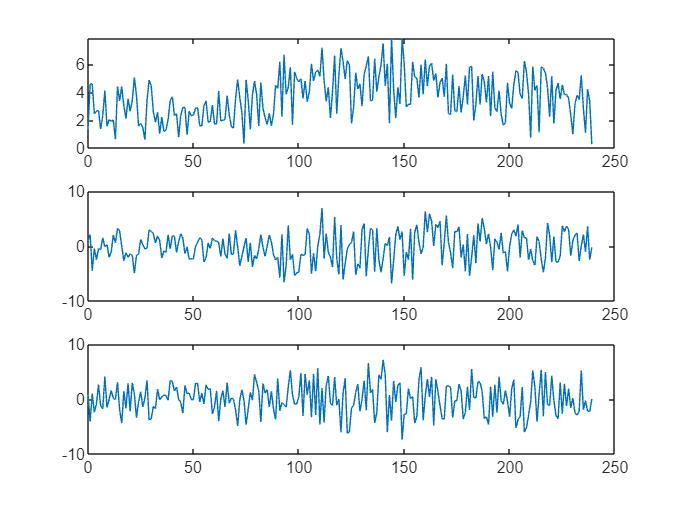

Block_number = 2

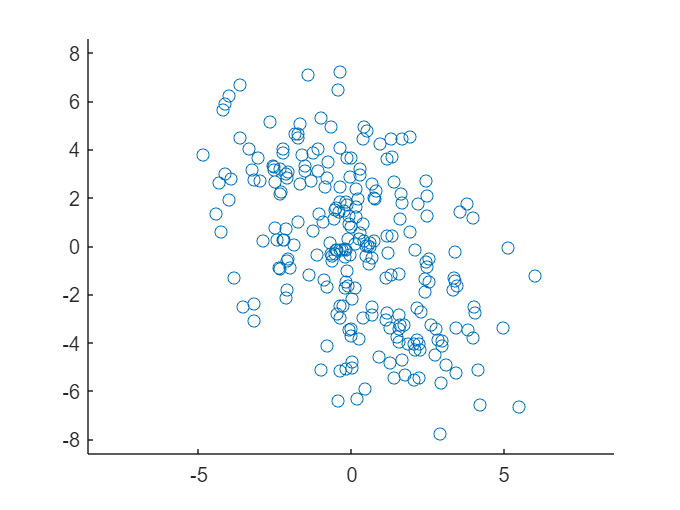

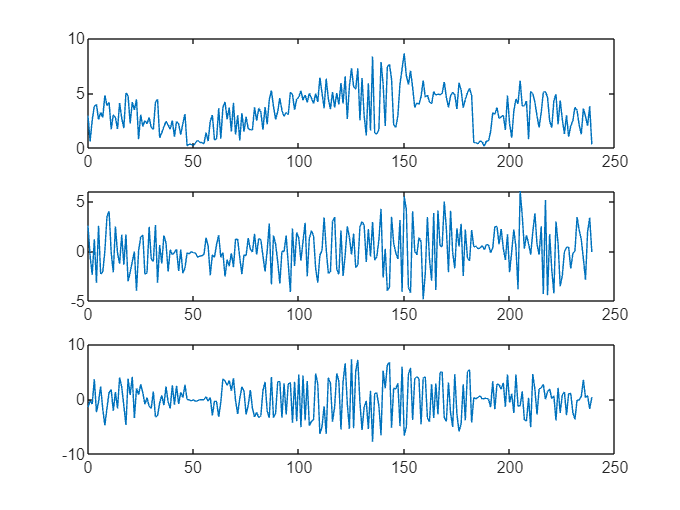

Block_number = 3

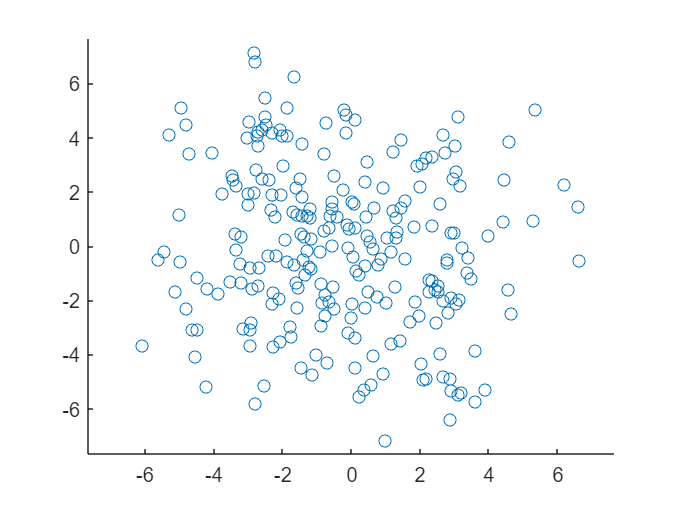

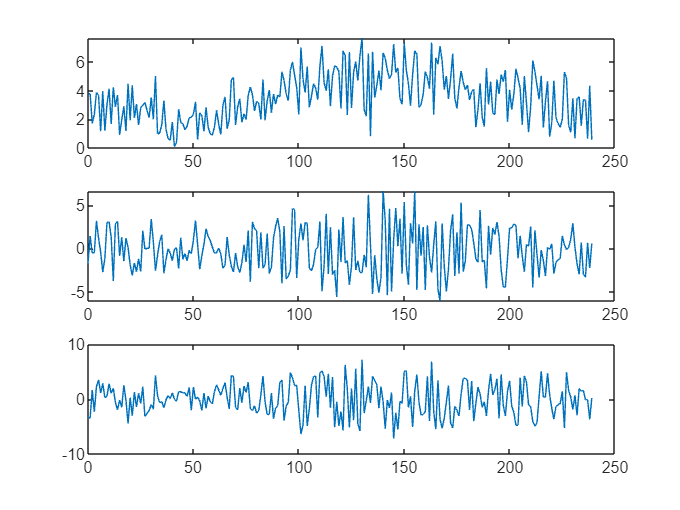

%extract 240 RE(subcarriers)
SCN = 0:239;
SC_series = zeros(4,240);
bias = 0;
SC_series(:,:) = fft_SSB(:,906+1:1145+1);
for i = 1:4
    Block_number = i-1
    figure
    scatter(real(SC_series(i,:)),imag(SC_series(i,:)))
    L = max(abs(SC_series(i,:)));
    axis([-L L -L L])
    %axis([-10 10 -10 10])
    figure
    subplot(3,1,1)
    plot(SCN, abs(SC_series(i,:)))
    subplot(3,1,2)
    plot(SCN, real(SC_series(i,:)))
    subplot(3,1,3)
    plot(SCN, imag(SC_series(i,:)))
end

% figure
% plot(SCN,SC_series)
% scatter(real(SC_series), imag(SC_series))

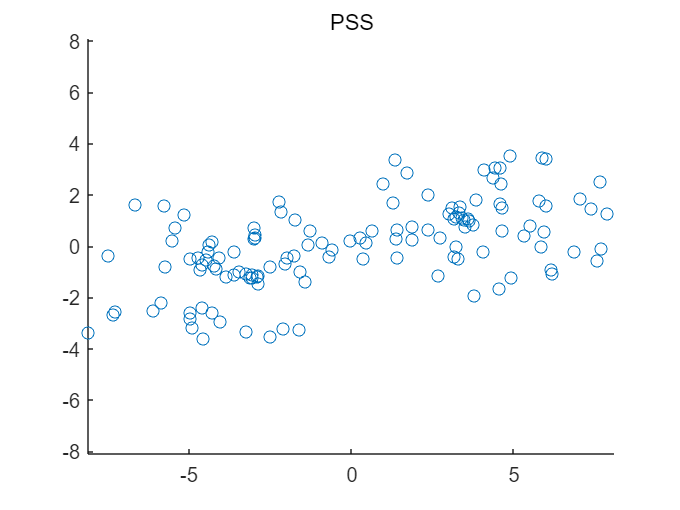

%extract PSS and SSS
PSS_orders = 56+1:182+1;
SSS_orders = PSS_orders;
zero2_orders = [48+1:55+1,183+1:191+1];
PSS = SC_series(1,PSS_orders);
SSS = SC_series(3,PSS_orders);
zero1_zone = SC_series(1,[]);
zero2_zone = SC_series(3,zero2_orders);
figure
scatter(real(PSS),imag(PSS))
L = max([abs(real(PSS)),abs(imag(PSS))]);
axis([-L L -L L])
title("PSS")

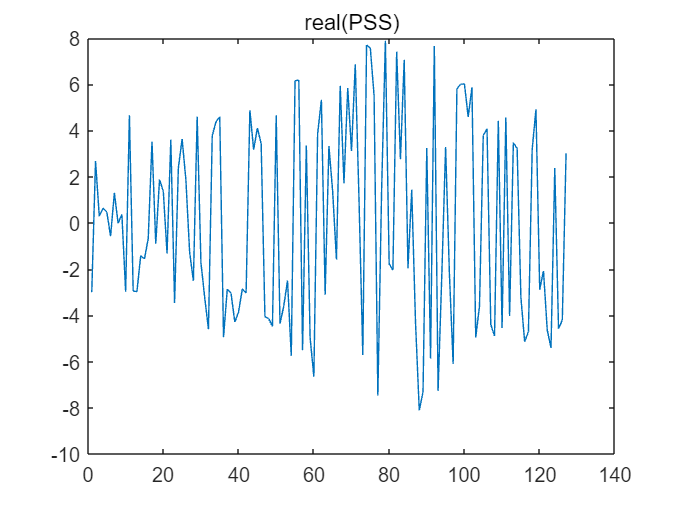

figure
plot(real(PSS))
title("real(PSS)")

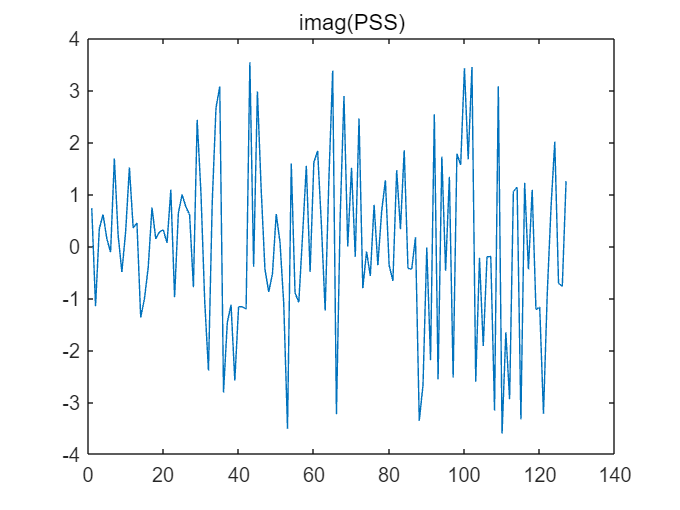

figure
plot(imag(PSS))
title("imag(PSS)")

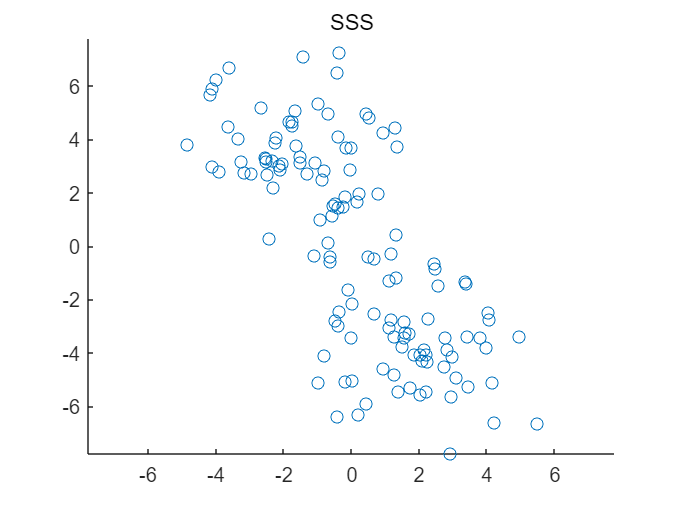


figure
scatter(real(SSS),imag(SSS))
title("SSS")
L = max([abs(real(SSS)),abs(imag(SSS))]);
axis([-L L -L L])

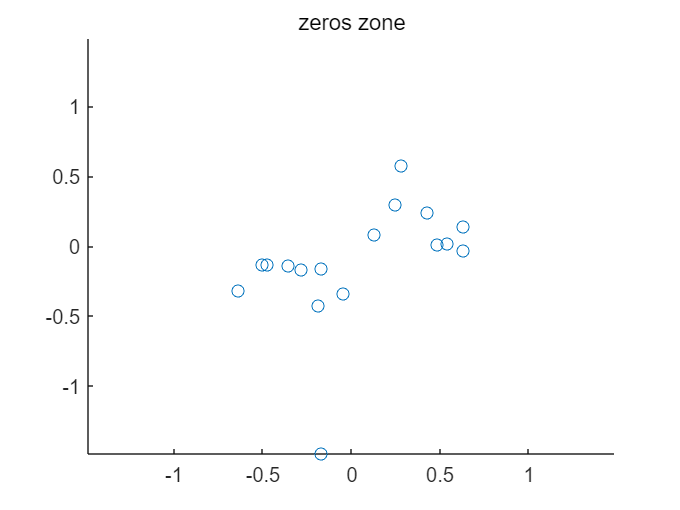

figure
scatter(real(zero2_zone),imag(zero2_zone))
title("zeros zone")
L = max([abs(real(zero2_zone)),abs(imag(zero2_zone))]);
axis([-L L -L L])

% (b) In low noise scenario, you can see clearly two dots. In high noise
% scenario, there are two aggregated circles. With channel frequency
% shaping, it distorts to some random distribution but somewhat on a line
% (c) done.
% 

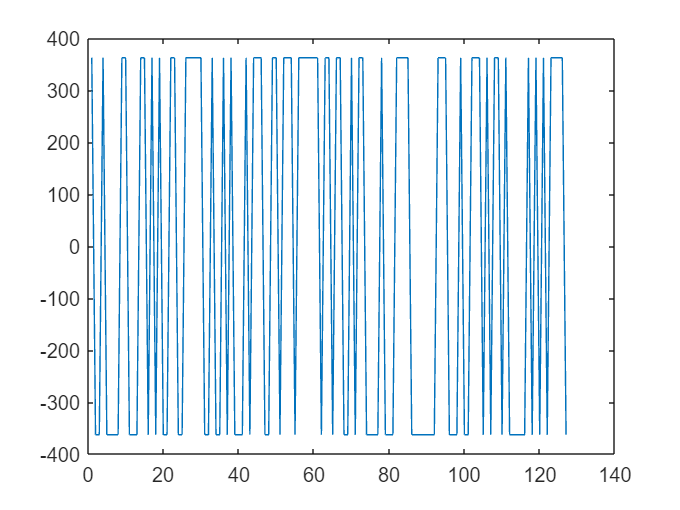

%doing channel estimation with PSS
PSS_2_given = nonzeros(fftshift(pssi_f));
plot(PSS_2_given)

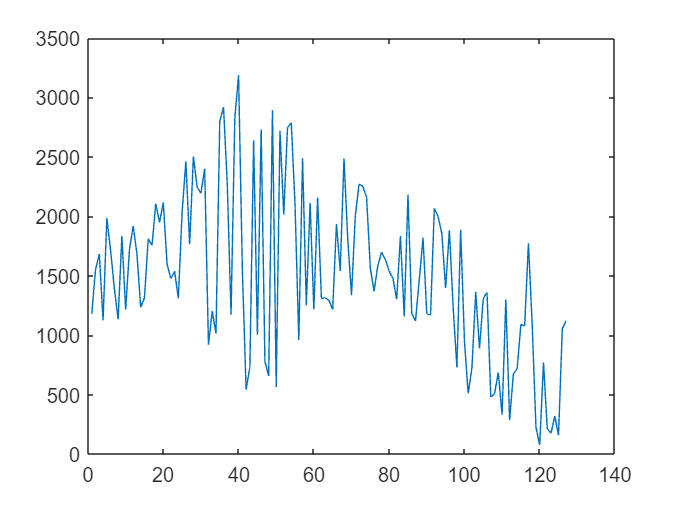

H_estimate = conj(PSS_2_given)'.*flip(PSS);
% (d) Here if we do the ML receiver in frequency domain, since |PSS|^2 = ones
% in frequency domain, the frequency reponse of channel stands out, 
% so we're equally doing the channel estimation. 
plot(abs(H_estimate))

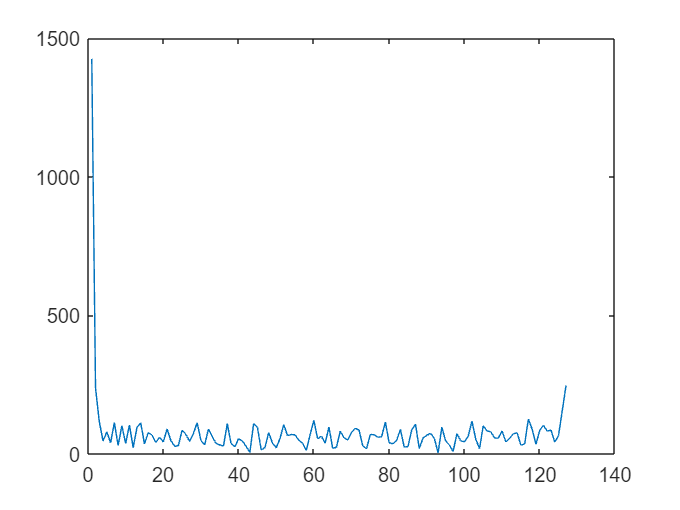

h_estimate = ifft((H_estimate));
plot(abs(h_estimate))

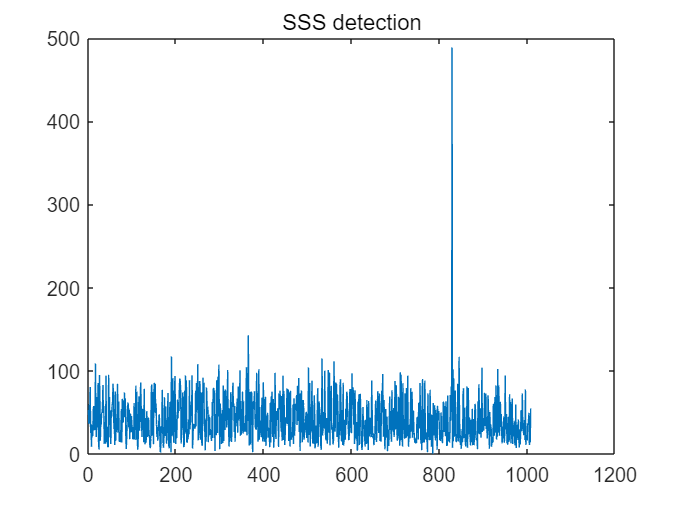

% SSS detection
% Here I implement MLD in a matrix form to detect SSS.
SSS_m = repmat(flip(SSS),1008,1);
Y_SSS = sum((SSS_m .* (d)), 2);
plot(abs(Y_SSS))
title('SSS detection')

[~,SSS_id] = max(abs(Y_SSS'));

N_id2 = mod(SSS_id-1,3)

N_id2 = 0

N_id1 = floor((SSS_id-1)/3)

N_id1 = 276

Cell_id = 3*N_id1 + N_id2

Cell_id = 828

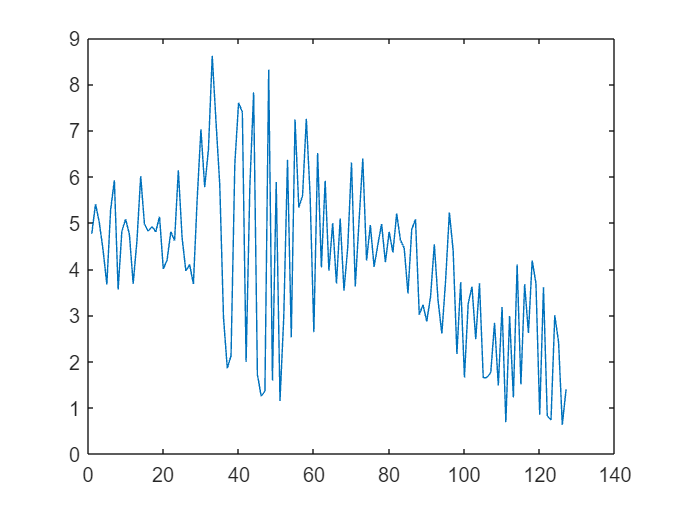

% possible channel estimation using SSS
D_i = d(SSS_id,:);
H = flip(SSS).*D_i;
plot(abs(H))

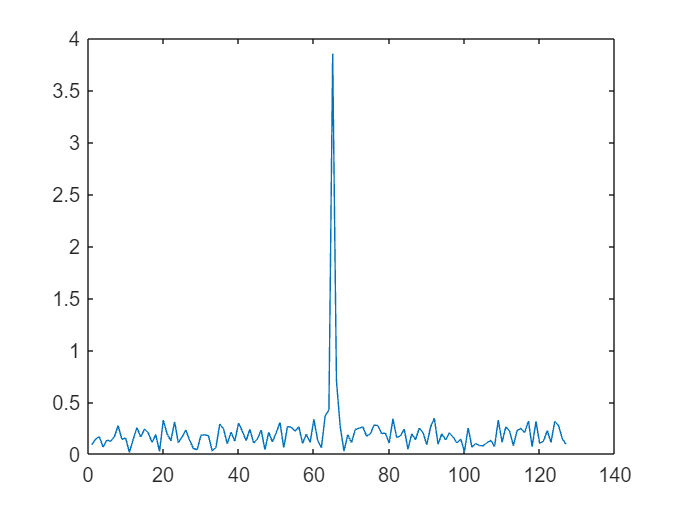

h = ifftshift(ifft(H,127));
plot(abs(h))

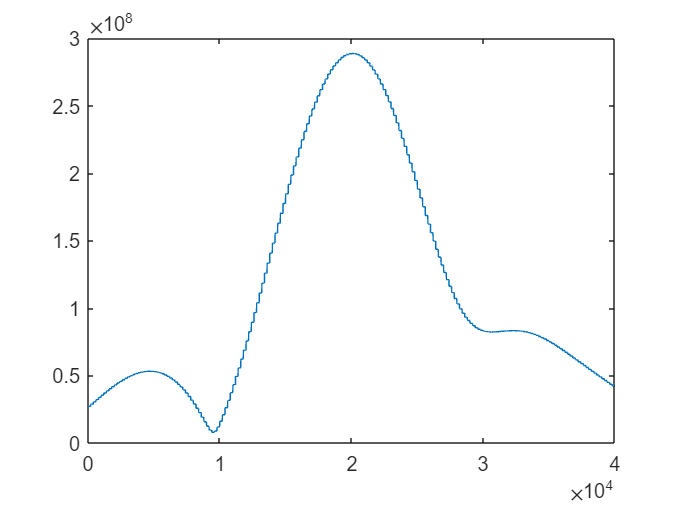

%residual timing and frequency errors detect
a0 = 0.01; b0 = 0.01;
N = 200;
a = linspace(-a0, a0,N);
b = linspace(-b0, b0,N);
n = 0; %n = 0 for PSS, n=2 for SSS
k = 1:127;
sssi = D_i;
pssi = PSS_2_given;
ML_value = [];
ML_values = [];
temp = 0;
for i = 1:N
    for j = 1:N
        tfE_sq_0 = exp(1j*2*pi.*k*a(i));
        tfE_sq_2 = exp(1j*2*pi.*k*a(i)+2*b(i));
        ML_value = sum((tfE_sq_0.*flip(PSS).*conj(pssi')+tfE_sq_2.*flip(SSS).*conj(sssi)).^2);
        ML_values = [ML_values ML_value];
        if ML_value > temp
            Max_value = ML_value;
            max_i = i;
            max_j = j;
        end
        temp = ML_value;
    end
end
plot(abs(ML_values))

a_offset = a(max_i)

a_offset = 0.0096

b_offset = b(max_j)

b_offset = -0.0100

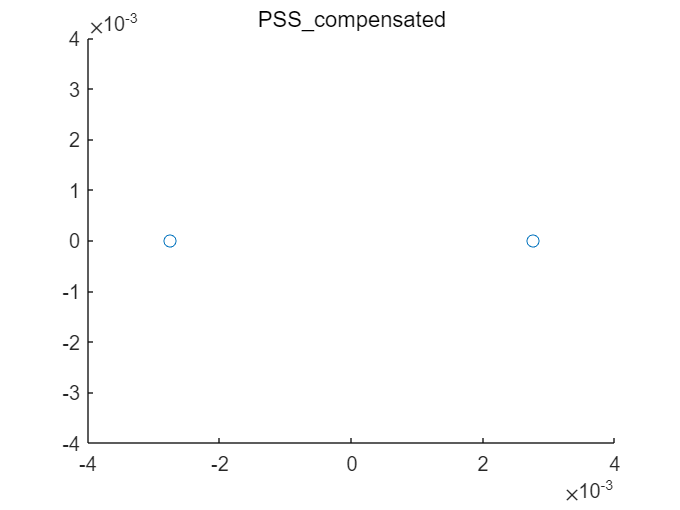

%final received PSS and SSS with Channel compansation
tfE_sq_0_max = exp(1j*2*pi.*k*a_offset);
tfE_sq_2_max = exp(+1j*2*pi.*k*a_offset+2*b_offset);
%PSS_compensated = tfE_sq_0_max.*flip(PSS)./H_estimate;
%SSS_compensated = tfE_sq_2_max.*flip(SSS)./H_estimate;
PSS_compensated = flip(PSS)./H_estimate;
SSS_compensated = flip(SSS)./H_estimate;
scatter(real(PSS_compensated),imag(PSS_compensated))
title('PSS\_compensated')
L = 0.004;
axis([-L, L, -L,L])

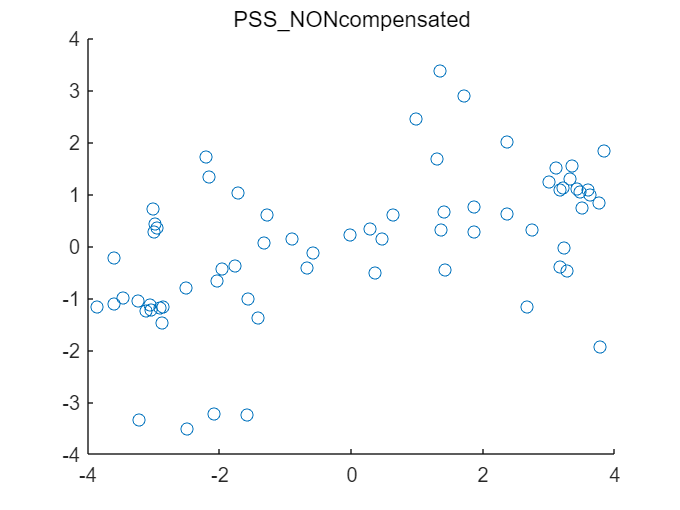

scatter(real(PSS),imag(PSS))
title('PSS\_NONcompensated')
L = 4;
axis([-L, L, -L,L])

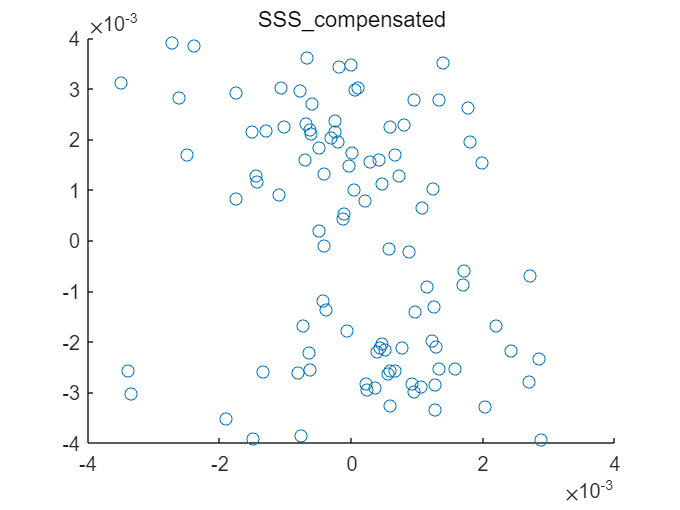

scatter(real(SSS_compensated),imag(SSS_compensated))
title('SSS\_compensated')
L = 0.004;
axis([-L, L, -L,L])

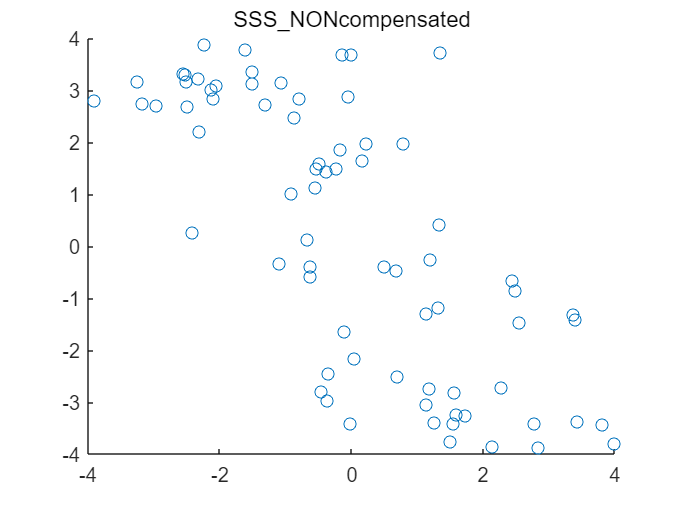

scatter(real(SSS),imag(SSS))
title('SSS\_NONcompensated')
L = 4;
axis([-L, L, -L,L])

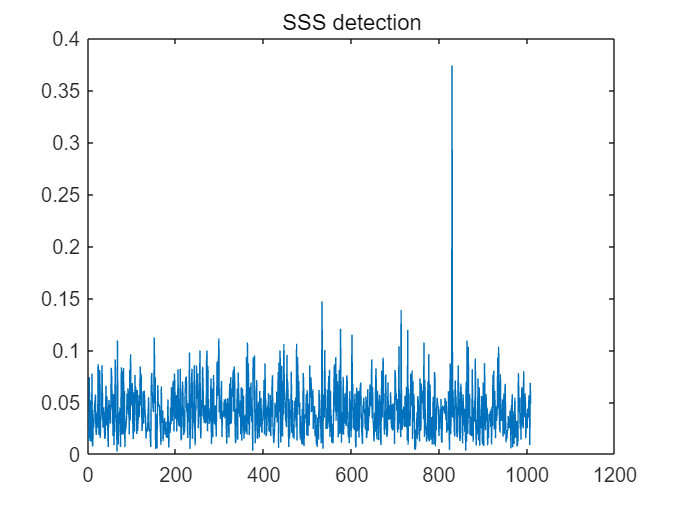


SSS_m = repmat(SSS_compensated,1008,1);
Y_SSS = sum((SSS_m .* (d)), 2);
plot(abs(Y_SSS))
title('SSS detection')

[~,SSS_id] = max(abs(Y_SSS'));

% final detected cell id
N_id2 = mod(SSS_id-1,3)

N_id2 = 0

N_id1 = floor((SSS_id-1)/3)

N_id1 = 276

Cell_id = 3*N_id1 + N_id2

Cell_id = 828

function BW = tdb_bandwidth(spc,fs,dB_value)
%change dB_value to define bandwidth
spc = 10*log(abs(spc));
peak = max(spc);
a = find(spc> peak-dB_value);
BW = length(a)/length(spc)*fs;
end

function spc = spd_plot(s, fs, Title, dB_value)
s_acr = xcorr(s,s);
fft_s = fft(s_acr)/length(s_acr);
fft_s = fftshift(abs(fft_s));
f = linspace(-fs/2,fs/2,length(s_acr));
spc = abs(fft_s);
plot(f,10*log(spc))
title(Title);
BW = tdb_bandwidth(spc,fs, dB_value);
disp("Bandwidth:")
disp(BW)
end

function [fft_s,f] = FFT(s, fs)
fft_s = fft(s,2048)/length(s);
fft_s = fftshift(fft_s);
f = linspace(-fs/2,fs/2,length(s));
end

function spc = fre_plot(s, fs, Title, dB_value)
fft_s = fft(s)/length(s);
fft_s = fftshift(fft_s);
f = linspace(-fs/2,fs/2,length(s));
spc = abs(fft_s);
plot(f,10*log(spc))
title(Title);
BW = tdb_bandwidth(spc,fs, dB_value);
disp("Bandwidth:")
disp(BW)
end

function [Y, pos, Y_max] = MLD(rx_sig, pss)
[l_r,~] = size(rx_sig);
[n,l_o] = size(pss);
l = l_r - l_o;
Y = zeros(l,n);
for i = 1:l
    Y(i,:) = sum((rx_sig(i:i+l_o - 1,:).*pss')).^2;
end
[Y_max,pos] = max(abs(Y));
end

function [Y, pos, Y_max] = MFD(rx_sig, pss)
MF_pss = flip(pss,2);
[m,~] = size(pss);
Y = [];
for i = 1:m
    Y = [Y;conv(MF_pss(i,:),rx_sig(:,i)').^2];
end
[Y_max,pos] = max(abs(Y'));
end

function [Y_joint,pos] = PSS_detc(rx_sig, pss0,pss1,pss2)
pss = [pss0;pss1;pss2];
Rx_sig = [rx_sig,rx_sig,rx_sig];
[Y_joint, pos, Y_max] = MLD(Rx_sig, pss);
[MAX_value,MAX_order] = max(Y_max);
if MAX_order == 1
    disp("pss0 detected")
elseif MAX_order == 2
    disp("pss1 detected")
elseif MAX_order == 3
    disp("pss2 detected")
end
disp('With value:')
MAX_value
disp('In position:')
pos(MAX_order)
%print(MAX_value)
end

function [Y_joint,pos,MAX_order] = PSS_MFdetc(rx_sig, pss0,pss1,pss2)
pss = [pss0;pss1;pss2];
Rx_sig = [rx_sig,rx_sig,rx_sig];
[Y_joint, pos, Y_max] = MFD(Rx_sig, pss);
[MAX_value,MAX_order] = max(Y_max);
if MAX_order == 1
    disp("pss0 detected")
elseif MAX_order == 2
    disp("pss1 detected")
elseif MAX_order == 3
    disp("pss2 detected")
end
disp('With value:')
MAX_value
disp('In position:')
pos(MAX_order)
%print(MAX_value)
end

function plot_together(x,Y)
figure
subplot(3,1,1)
plot(x,Y(:,1)',"Color","b")
title("pss0 Detect")
subplot(3,1,2)
plot(x,Y(:,2)',"Color","r")
title("pss1 Detect")
subplot(3,1,3)
plot(x,Y(:,3)',"Color","g")
title("pss2 Detect")
end

function [best_offset_freq, max_outcome, freq_scan] = freq_offset_detect(pssi,rx,fre_band,type,fs)
%if type = 1, ML; if type = 2, MF
%never use 1, far too slow!!!
Fre = -fre_band:0.1:fre_band;%testing frequency
best_offset_freq = -10;
freq_scan = zeros(1, length(Fre));%outcome storage
n = 1: length(pssi);
max_outcome = 0;
for fre = 1:length(Fre)
    offset_seq = exp(-2*pi.*n*1j*Fre(fre)*1e3/fs);
    if type == 1
        [~, ~, freq_scan(fre)] = MLD(rx, offset_seq.*pssi);
    end
    if type == 2
        [~, ~, freq_scan(fre)] = MFD(rx, offset_seq.*pssi);
    end
    if freq_scan(fre) > max_outcome
        max_outcome = freq_scan(fre);
        best_offset_freq = Fre(fre);
        %Best_fre = fre;
    end
    %disp("Testing order:")
    %fre
end
figure
plot(Fre,freq_scan)
end
